# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

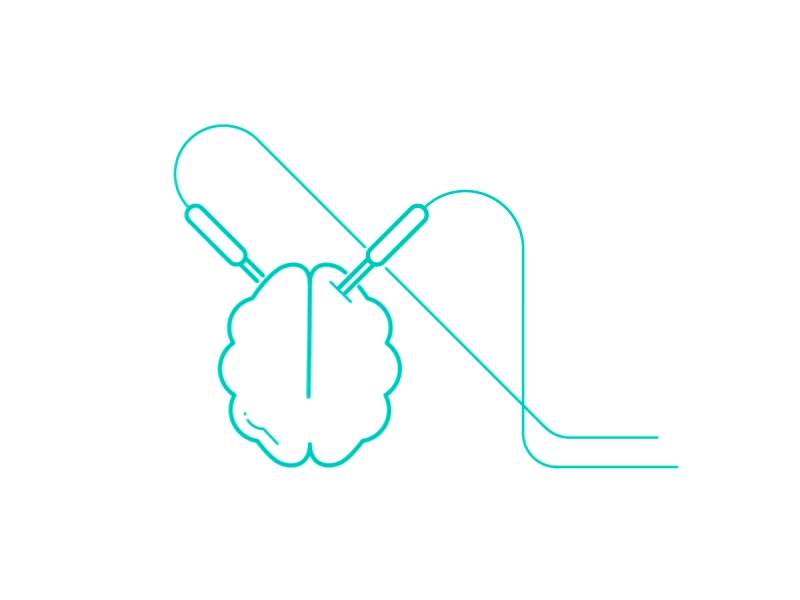

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\ChangeDetection\ChangeDetection'];
Deci.SubjectList = 'gui';
Deci.Step               = 1;
Deci.Folder.Version     = ['C:\Users\User\Desktop\ChangeDetection\ProcessedData'];
Deci.Retroactive  = true;
Deci.PCom =true; 

## 1. Trial Definitions

%Deci.DT.Type = 'colorkbeeg_trl';
Deci.DT.Starts     = {120};         %Cell Array of Markers for ETs Start.
Deci.DT.Ends       = {121};         %Cell Array of Markers for ETs End.
Deci.DT.Markers    = {[10 11] [61 62]  [51 52 53] [81 82 83]};
%                       L/R      change            H        RCor
Deci.DT.Locks      = [13 16];
%                     S1 S2 R
Deci.DT.Toi        = [-.4 1.2];
Deci.DT.trlcheck = false;
% Cell Array of Markers for Block Starts

## 2. PreProcessing Steps

Deci.PP = [];
%Deci.PP.filter.bpfreq = [1 30];
%Deci.PP.filter.bpfilter = 'yes';
%Deci.PP.More.channel = {'TP10' 'TP9' 'PO3' 'PO4' 'O1' 'O2' 'PO7' 'PO8' 'P7' 'P8' 'TVEOG' 'BVEOG' 'RHEOG' 'LHEOG'};


Deci.ICA.do = false;

## 3. Artifact Rejection

Deci.Art.do = false;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.Manual_Trial_Rejection = false;
Deci.Art.ShowArt =  true;

## 4. Analysis

Deci.Analysis.Laplace       =false;                                                               % Uses Captrak .bvct file with same name in RawData Folder
Deci.Analysis.DownSample    = 500;

%CDA
  
Deci.Analysis.Channels = {'PO3' 'PO4' 'O1' 'O2' 'PO7' 'PO8' 'P7' 'P8'};
Deci.Analysis.Locks         = [1];                                                          % Which Lock to Analyze
Deci.Analysis.LocksTitle    = {'Delay Onset'};                      % Folder Title to save each Lock as
%Deci.Analysis.Conditions    = {[10 11 51 81] [10 11 52 81] [10 11 53 81] [10 11 51 82 83] [10 11 52 82 83] [10 11 53 82 83]};
Deci.Analysis.Conditions    = {[10 11 51 81] [10 11 52 81] [10 11 53 81]};
Deci.Analysis.HemifieldFlip.do = true;
Deci.Analysis.HemifieldFlip.Markers = [10 11];

Deci.Analysis.CondTitle     = {'Set Size 1' 'Set Size 2' 'Set Size 3'};
%Deci.Analysis.CondTitle     = {'Set Size 1' 'Set Size 2' 'Set Size 3' 'Set Size 1 Inc' 'Set Size 2 Inc' 'Set Size 3 Inc'};
Deci.Analysis.Version = [Deci.Folder.Version];
Deci.Analysis.ERP.do  = true;

Deci.Analysis.Toilim = [-.4 1.2];
Deci.Analysis.Toi = [-.4 1.2];

## 5. Plotting

Deci.Plot.Version = [Deci.Analysis.Version];
Deci.Plot.Figures      = [false true true true];
Deci.Plot.Math         = {};           % Condition Math done after Bsl, Condition Indexes are appended on.
Deci.Plot.Draw         = {[1 2 3] [1] [2] [3]};                   % Cell array of Condition Index for each figure

Deci.Plot.Title        = {'Set Sizes All' 'Set Sizes 1' 'Set Sizes 3' 'Set Sizes 5'};          % Title for each figure
Deci.Plot.Subtitle     = {{'1' '3' '5'} {'1'} {'3'} {'5'}};     % Cell array of strings of subtitles for each Condition

Deci.Plot.BslRef = 'Delay Onset';
Deci.Plot.Lock =   'Delay Onset';
Deci.Plot.Bsl     = [-0.4 -0.2];

%Deci.Run.Freq =false;
Deci.Run.ERP =true;
Deci.Run.Extra = false;
Deci.Run.Behavior = false;

Deci.Plot.GrandAverage = true;

Deci.Plot.Hemiflip.do = true;
Deci.Plot.Hemiflip.Type = 'Both';

Deci.Plot.Topo.do    =false;
Deci.Plot.Topo.Toi     =[.2 .4];                   % Time of Interest
Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest

Deci.Plot.Wire.do    =true;
Deci.Plot.Wire.Channel =   {'PO3' 'PO4' 'O1' 'O2' 'PO7' 'PO8' 'P7' 'P8'};            % Channel of Interest
Deci.Plot.Wire.Toi     = [-.5 1.5];                   % Time of Interest

Deci.Plot.Bar.do    =false;
Deci.Plot.Bar.Toi     = [.3 .9];                    % Time of Interest
Deci.Plot.Bar.Channel =  {'PO3' 'PO4' 'O1' 'O2' 'PO7' 'PO8' 'P7' 'P8'};            % Channel of Interest

Deci.Plot.Stat.do = true ; % Will only work if for large subject pools
if Deci.Plot.Stat.do
    Deci.Plot.Stat.Type = 'Anova/T-test';
    Deci.Plot.Stat.alpha = .05;
    Deci.Plot.Stat.correctm = 'fdr';
end



#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';
Deci.Plot.Behv.WriteExcel = true;

Deci.Plot.Behv.Acc.Figure = [true];
Deci.Plot.Behv.Acc.Total = {{[1 4] [2 5] [3 6]}};
Deci.Plot.Behv.Acc.Subtotal = {{1 2 3}};
Deci.Plot.Behv.Acc.Title = {'Set Size Correctness' };
Deci.Plot.Behv.Acc.Subtitle = {{'Set Size 1 Correctness' 'Set Size 3 Correctness' 'Set Size 5 Correctness'}};

Deci.Plot.Behv.Acc.Block =  @ceil;
Deci.Plot.Behv.Acc.Collapse.Trial =true;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = true;
Deci.Plot.Behv.Acc.Collapse.Movmean =  false;

Deci.Plot.Behv.RT.Figure = [true];
Deci.Plot.Behv.RT.Draw = {{1 2 3}};
Deci.Plot.Behv.RT.Title = {'Correct Trials RT'};
Deci.Plot.Behv.RT.Subtitle = {{'1' '3' '5'}};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block =  @ceil;
Deci.Plot.Behv.RT.Collapse.Trial =true;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = true;


Deci_Backend(Deci);

Running Deci for 25 subjects
 
----------------------
Starting DefineTrialor
Found 214 trials out of 214 for SS06
Found 215 trials out of 215 for SS07
Found 216 trials out of 216 for SS08
Found 216 trials out of 216 for SS10
Found 216 trials out of 216 for SS11
Found 216 trials out of 216 for SS17
Found 215 trials out of 215 for SS18
Found 216 trials out of 216 for SS20
Found 216 trials out of 216 for SS21
Found 214 trials out of 214 for swm02
Found 116 trials out of 116 for swm03
Found 216 trials out of 216 for swm04
Found 213 trials out of 213 for swm06
Found 216 trials out of 216 for swm07
Found 214 trials out of 214 for swm08
Found 216 trials out of 216 for swm09
Found 216 trials out of 216 for swm11
Found 215 trials out of 215 for swm12
Found 216 trials out of 216 for swm13
Found 214 trials out of 214 for swm14
Found 216 trials out of 216 for swm16
Found 216 trials out of 216 for swm17
Found 216 trials out of 216 for swm19
Found 216 trials out of 216 for swm21
Found 210 trials out